# Estimation of Randomly Occurring Deterministic Disturbances

## Guide to using the MATLAB code in this directory

Author:    Bill Tubbs

Date:    June 2022

Main files used in this tutorial:

- `KalmanFilter.m`

- `MKFObserverSF.m`

- `MKFObserverSP.m`

- `sample_random_shocks.m`

- `sys_rodin_step.m`

Other dependencies required:

- `check_dimensions.m`

- `combinations.m`

- `combinations_lte.m`

- `n_filters.m`

- `prob_Gammas.m`

- `prob_gamma.m`

- `rodd_tf.m`

clear all
set(0, 'DefaultTextInterpreter', 'none')
set(0, 'DefaultLegendInterpreter', 'none')
set(0, 'DefaultAxesTickLabelInterpreter', 'none')

## 1. Generating randomly-occurring shocks

Generate a sample sequence of the random variable $w_{p,i} \left(k\right)$ described in Robertson et al. (1995).

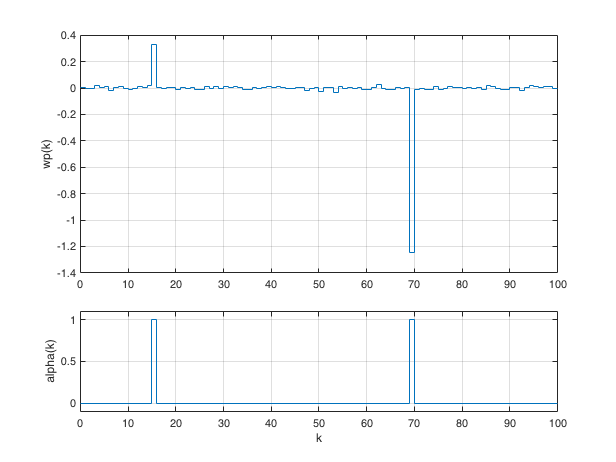

% Reset random number generator
seed = 22;
rng(seed)

% Sequence length
nT = 100;

% RODD random variable parameters
epsilon = 0.01;
sigma_w = [0.01; 1];

[Wp, alpha] = sample_random_shocks(nT+1, epsilon, sigma_w(2), sigma_w(1));

figure(1)
subplot(3,1,[1 2])
stairs(0:nT,Wp); grid on
ylabel('wp(k)')
subplot(3,1,3)
stairs(0:nT, alpha); grid on
ylim([-0.1 1.1])
xlabel('k')
ylabel('alpha(k)')

## 2. First order SISO system with one input disturbance

Consider the following linear dynamic system which consists of a process transfer function, an additive input disturbance, a measurement noise at the output, and a Kalman filter:

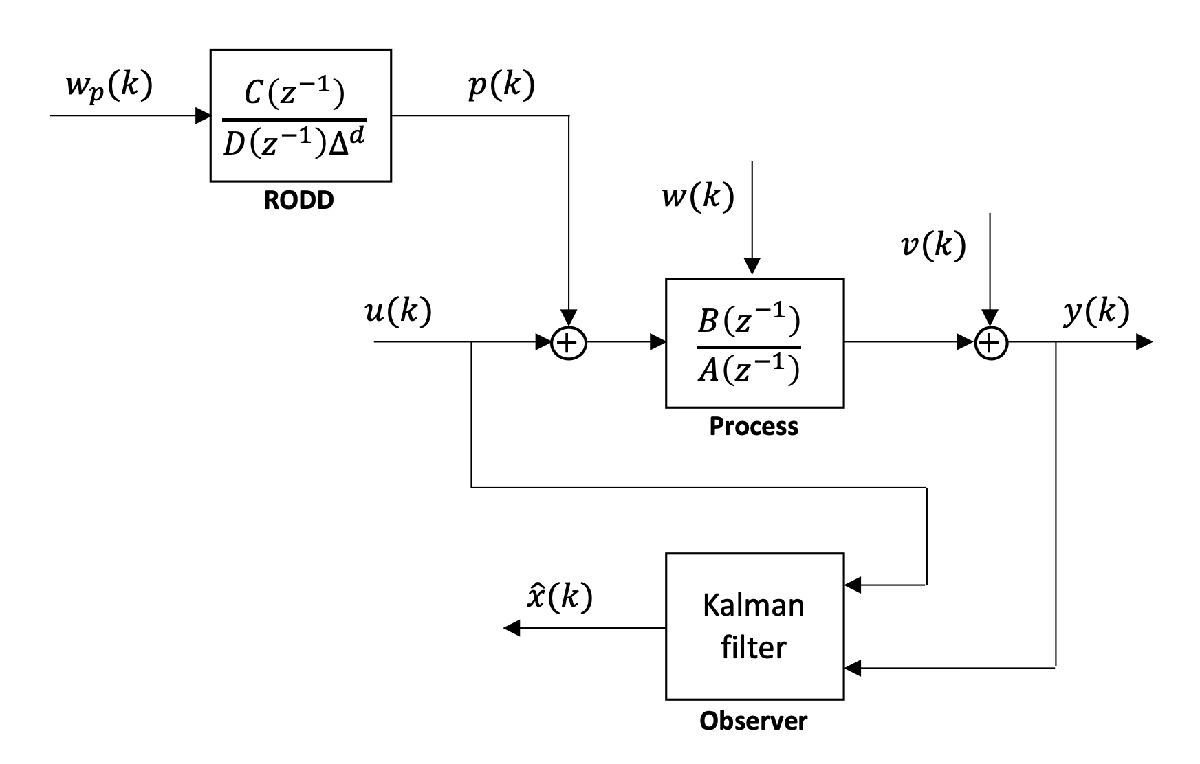

In this example, we will use a discrete system model defined in the file:

- `sys_rodin_step.m`

% Import system
sys_rodin_step
% Process transfer function
Gd

Gd =
 
    0.3
  -------
  z - 0.7
 
Sample time: 0.5 seconds
Discrete-time transfer function.



% RODD transfer function
HDd

HDd =
 
    1
  -----
  z - 1
 
Sample time: 0.5 seconds
Discrete-time transfer function.



The state-space representation of the augmented system is included in `sys_rodin_step.m`.

A, B, C, D, Ts

A =     0.7000    1.0000
         0    1.0000


B =      1     0
     0     1


C =     0.3000         0


D =      0     0


Ts = 0.5000

Gpss

Gpss =
 
  A = 
        x1   x2
   x1  0.7    1
   x2    0    1
 
  B = 
       u1  u2
   x1   1   0
   x2   0   1
 
  C = 
        x1   x2
   y1  0.3    0
 
  D = 
       u1  u2
   y1   0   0
 
Sample time: 0.5 seconds
Discrete-time state-space model.



n, nu, ny

n = 2

nu = 1

ny = 1

Simulate system

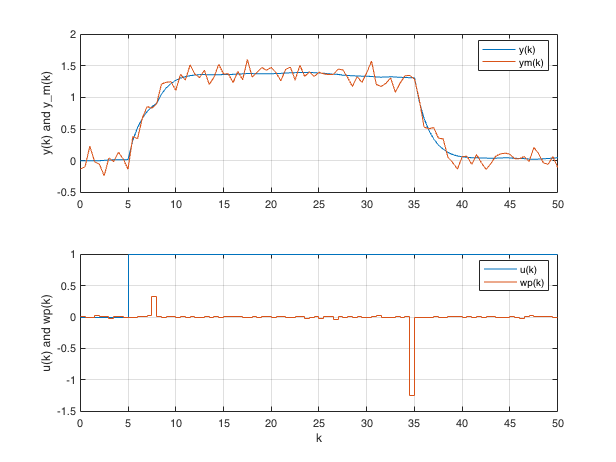

X0 = zeros(n,1);
t = Ts*(0:nT)';
U = zeros(nT+1,1);
U(t>=5) = 1;
[Y,T,X] = lsim(Gpss,[U Wp],t,X0);
V = sigma_M*randn(nT+1, 1);
Ym = Y + V;  % measurement

figure(2)
subplot(2,1,1)
plot(t,Y,t,Ym); grid on
ylabel('y(k) and y_m(k)')
legend('y(k)', 'ym(k)')
subplot(2,1,2)
stairs(t, [U Wp]); grid on
xlabel('k')
ylabel('u(k) and wp(k)')
legend('u(k)', 'wp(k)')

### 3. Kalman filter simulation

The function `kalman_filter` can be used to instantiate a struct variable containing the parameters to simulate a standard Kalman filter:

% Parameters
P0 = eye(n);
Q = diag([0.01^2 0.1^2]);
R = 0.1^2;
Bu = B(:,1);  % observer model without unmeasured inputs
KF1 = KalmanFilter(A,Bu,C,Ts,P0,Q,R,'KF1');
KF1

KF1 =   KalmanFilter with properties:

    xkp1_est: [2×1 double]
    ykp1_est: 0
        Pkp1: [2×2 double]
           K: [2×1 double]
           Q: [2×2 double]
           R: 0.0100
          P0: [2×2 double]
           n: 2
          nu: 1
          ny: 1
           A: [2×2 double]
           B: [2×1 double]
           C: [0.3000 0]
           D: []
          Ts: 0.5000
       label: "KF1"
          x0: [2×1 double]
        type: "KF"


The object has an `update` method which is used to simulate it in discrete time-steps

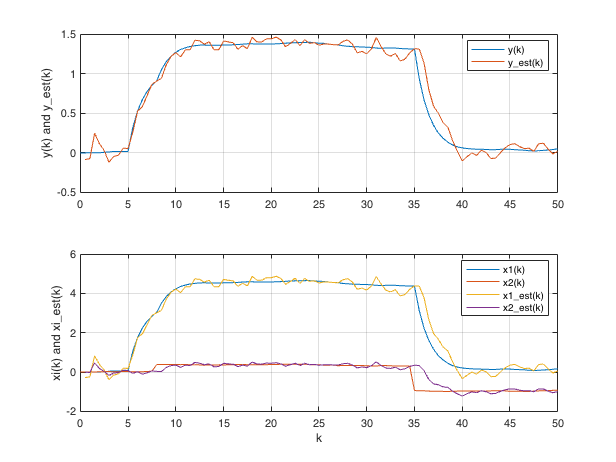

% Arrays to store simulation results
Xk_est = nan(nT+1,n);
Yk_est = nan(nT+1,ny);
obs = KF1;
for i = 1:nT
    uk = U(i,:)';
    yk = Ym(i,:)';
    obs.update(yk, uk);
    Xk_est(i+1,:) = obs.xkp1_est';
    Yk_est(i+1,:) = obs.ykp1_est';
end

figure(3)
subplot(2,1,1)
plot(t,[Y Yk_est]); grid on
ylabel('y(k) and y_est(k)')
legend('y(k)','y_est(k)')
subplot(2,1,2)
plot(t, [X Xk_est]); grid on
xlabel('k')
ylabel('xi(k) and xi_est(k)')
legend('x1(k)','x2(k)','x1_est(k)','x2_est(k)')

% Calculate mean-squared error in state estimates
mse = mean((X(2:end,:) - Xk_est(2:end,:)).^2, [1 2])

mse = 0.0917

### 4. Sub-optimal multi-model observer simulation

The `MKFObserver_SF` class can be used to instantiate a sub-optimal multi-model observer which uses sequence fusion as described by Robertson *et al. *(1998).

Use the help function for details on this function.

help MKFObserverSF

  Multi-model Kalman Filter class definition
 
  Object class for simulating a multi-model observer for 
  state estimation in the presence of randomly-occurring 
  deterministic disturbances (RODDs) as described in 
  Robertson et al. (1995, 1998).
 
  obs = MKFObserverSF(A,B,C,Ts,u_meas,P0,epsilon, ...
      sigma_wp,Q0,R,f,m,d,label,x0)
 
  Arguments:
    A, B, C : Matrices of the discrete time state-space
        system representing the augmented system (including
        disturbances and unmeasured inputs).
    Ts : Sample period.
    u_meas : binary vector indicating measured inputs.
    P0 : Initial value of covariance matrix of the state
        estimates.
    epsilon : probability of a shock disturbance.
    sigma_wp : standard deviation of shock disturbances.
    Q0 : Process noise covariance matrix (n, n) with 
         variances for each state on the diagonal. The  
         values for states impacted by the unmeasured
         input disturbances should be 

% Define multi-model filter
P0 = eye(n);
Q0 = diag([0.01^2 0]);
R = 0.1^2;
f = 15;  % fusion horizon
m = 1;  % maximum number of shocks
d = 3;  % spacing parameter
MKF1 = MKFObserverSF(A,B,C,Ts,u_meas,P0,epsilon,sigma_wp, ...
    Q0,R,f,m,d,'MKF1');
MKF1

MKF1 =   MKFObserverSF with properties:

             u_meas: [2×1 logical]
                  m: 1
              alpha: 0.0297
               beta: 0.9917
              p_seq: [6×1 double]
            p_gamma: [2×1 double]
                 Q0: [2×2 double]
            epsilon: 0.0100
           sigma_wp: [0.0100 1]
                 Ts: 0.5000
                  n: 2
                 nu: 1
                 ny: 1
                 nj: 2
                  d: 3
                  f: 15
               n_di: 5
             n_filt: 6
                  A: {[2×2 double]  [2×2 double]}
                  B: {[2×1 double]  [2×1 double]}
                  C: {[0.3000 0]  [0.3000 0]}
                  Q: {[2×2 double]  [2×2 double]}
                  R: {[0.0100]  [0.0100]}
                seq: {6×1 cell}
      merge_idx_seq: [6×5 double]
             gamma0: [6×1 double]
                  T: [2×2 double]
              label: "MKF1"


Inspect observer parameters

% Disturbance sequences for each filter
cell2mat(MKF1.seq)

ans = 6×5 int16 matrix
   0   0   0   0   0
   1   0   0   0   0
   0   1   0   0   0
   0   0   1   0   0
   0   0   0   1   0
   0   0   0   0   1


% Sequence probabilities (unconditioned)
MKF1.p_seq

ans =     0.8601
    0.0263
    0.0263
    0.0263
    0.0263
    0.0263


% Total probability of all sequences modelled (ideally, should be > 0.99)
MKF1.beta

ans = 0.9917

The `update` method is used to simulate the observer, same as for the Kalman filter above.

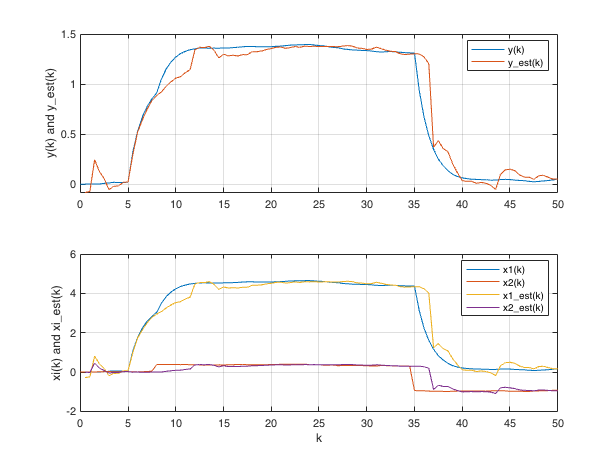

% Arrays to store simulation results
Xk_est = nan(nT+1,n);
Yk_est = nan(nT+1,ny);
obs = MKF1;
for i = 1:nT
    uk = U(i,:)';
    yk = Ym(i,:)';
    obs.update(yk, uk);
    Xk_est(i+1,:) = obs.xkp1_est';
    Yk_est(i+1,:) = obs.ykp1_est';
end

figure(4)
subplot(2,1,1)
plot(t,[Y Yk_est]); grid on
ylabel('y(k) and y_est(k)')
legend('y(k)','y_est(k)')
subplot(2,1,2)
plot(t, [X Xk_est]); grid on
xlabel('k')
ylabel('xi(k) and xi_est(k)')
legend('x1(k)','x2(k)','x1_est(k)',['x2_est(k)'])

% Calculate mean-squared error in state estimates
mse = mean((X(2:end,:) - Xk_est(2:end,:)).^2, [1 2])

mse = 0.1280

### 5. Multiple model observer with sequence pruning

The `MKFObserverSP` class can be used to instantiate a sub-optimal multi-model observer which uses sequence pruning as described by Eriksson and Isaksson (1996).

Use the help function for details on this function.

help MKFObserverSP

  Multi-model Kalman Filter class definition
 
  Object class for simulating a multi-model observer
  using the adaptive forgetting through multiple models 
  (AFMM) algorithm for state estimation in the presence of 
  infrequently-occurring deterministic disturbances, as 
  described in Eriksson and Isaksson (1996).
 
  Uses a sequence pruning method described in Eriksson and
  Isaksson (1996):
  - At the updates, let only the most probable sequence,
    i.e. with the largest weight of all the sequences
    split into 2 branches.
  - After the update is completed, remove the sequence
    with the smallest weight.
  - Renormalize the remaining weights to have unit sum.
 
  Restriction to above rules:
  - Do not cut branches immediately after they are born.
    Let there be a certain minimum life length for all 
    branches.
 
  obs = MKFObserverSP(A,B,C,Ts,u_meas,P0,epsilon, ...
      sigma_wp,Q0,R,n_filt,f,n_min,label,x0)
 
  Creates a struct for simulating a multi-m

% Define multi-model filter
P0 = eye(n);
Q0 = diag([0.01^2 0]);
R = 0.1^2;
f = 10;  % sequence history length
n_filt = 5;  % number of filters
n_min = 2;  % minimum life of cloned filters
MKF2 = MKFObserverSP(A,B,C,Ts,u_meas,P0,epsilon,sigma_wp, ...
    Q0,R,n_filt,f,n_min,'AFMM1');

Inspect selected observer parameters

% Initial filter probabilities
MKF2.p_seq_g_Yk

ans =      1
     0
     0
     0
     0


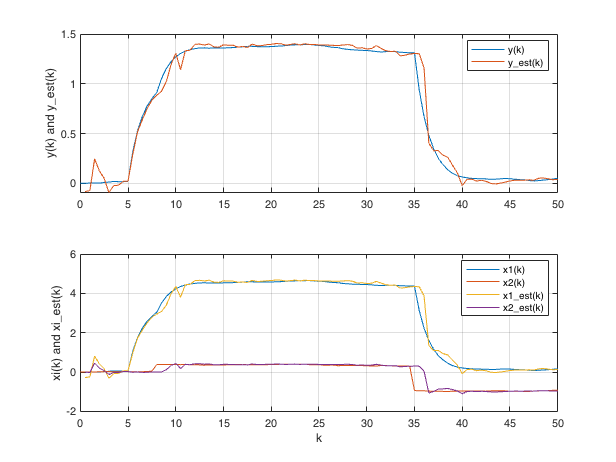

% Arrays to store simulation results
Xk_est = nan(nT+1,n);
Yk_est = nan(nT+1,ny);
obs = MKF2;
for i = 1:nT
    uk = U(i,:)';
    yk = Ym(i,:)';
    obs.update(yk, uk);
    Xk_est(i+1,:) = obs.xkp1_est';
    Yk_est(i+1,:) = obs.ykp1_est';
end

figure(4)
subplot(2,1,1)
plot(t,[Y Yk_est]); grid on
ylabel('y(k) and y_est(k)')
legend('y(k)','y_est(k)')
subplot(2,1,2)
plot(t, [X Xk_est]); grid on
xlabel('k')
ylabel('xi(k) and xi_est(k)')
legend('x1(k)','x2(k)','x1_est(k)',['x2_est(k)'])

% Calculate mean-squared error in state estimates
mse = mean((X(2:end,:) - Xk_est(2:end,:)).^2, [1 2])

mse = 0.0602

## References

- Robertson, D. G., Kesavan, P., & Lee, J. H. (1995). Detection and estimation of randomly occurring deterministic disturbances. *Proceedings of 1995 American Control Conference - ACC’95*, *6*, 4453–4457. [https://doi.org/10.1109/ACC.1995.532779.](https://doi.org/10.1109/ACC.1995.532779.)

- Eriksson, P.-G., & Isaksson, A. J. (1996). Classification of Infrequent Disturbances. *IFAC Proceedings Volumes*, *29*(1), 6614–6619. [https://doi.org/10.1016/S1474-6670(17)58744-3](https://doi.org/10.1016/S1474-6670(17)58744-3).